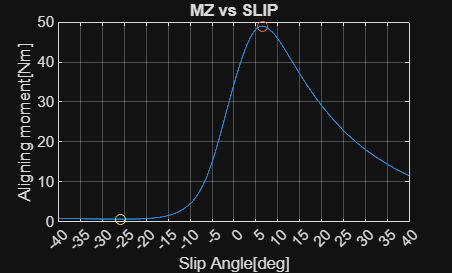

clear
load("mfparams_2.mat");

CoeffLong = Tire_Coefficients(mfparams, 'c_long');
SFLong = Tire_Scaling_Factors(mfparams, 'sf_long');

CoeffLat = Tire_Coefficients(mfparams, 'c_lat'); 
SFLat = Tire_Scaling_Factors(mfparams, 'sf_lat');

CoeffAlign = Tire_Coefficients(mfparams, 'c_align'); 
SFAlign = Tire_Scaling_Factors(mfparams, 'sf_align');

%%settings
%pressure [bar]
pressure = 0.7;
%camber angle
gamma = 0;                            
% Normal force
Fz = 1000;                              
% slip angle
alpha= -40:0.05:40;
%slip ratio
kappa = 0;

% calculation of Mz0
Mz = CombinedAligningMF(CoeffAlign,SFAlign,CoeffLong,SFLong,alpha,kappa,Fz,gamma,pressure,CoeffLat,SFLat);

%PLOTTING
plot(alpha,Mz);
xlabel("Slip Angle[deg]");
xticks(-100:5:100);

ylabel("Aligning moment[Nm]");


title("MZ vs SLIP");

grid

hold on

% max and min
[MzMax, MzMaxIdx] = max(Mz);
scatter(alpha(:,MzMaxIdx),MzMax);
alphaMax = alpha(MzMaxIdx);

[MzMin, MzMinIdx] = min(Mz);
scatter(alpha(:,MzMinIdx),MzMin);
alphaMin = alpha(MzMinIdx);
hold off